# IET-GPR documentation

## Example 2

Process data from a GSSI-StructureScan Mini GPR.

### Start the IET-GPR software and load a GPR file

See Example 1 for details of this section.

clear
run('..\ietgpr')
filename = 'data\File____001.dzt';
[data, dataHeader] = readdzt(filename);
relPerm = 9;

### Remove the linear offset

Remove the linear offset of the data using the function **dcoffset** or **linearoffset**.

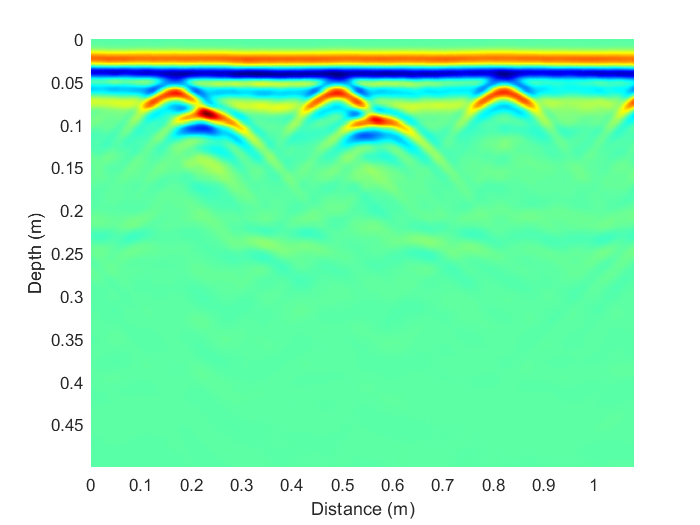

pdata1 = linearoffset(data);
plotbscan(pdata1, dataHeader, relPerm);

### Apply a gain function

Apply a gain to the data to improve the visualization. Currently, the following gain functions can be applied:

- **lingain**: applies a custom linear gain to the data.

- **expgain**: applies a custom exponencial gain to the data.

- **agcgain**: applies an automatic gain control to the data.

- **iadgain1**: applies an inverse amplitude decay to the data, based on the curve $y=a\;\exp \left(-b\;x\right)+c$.

- **iadgain2**: applies an inverse amplitude decay to the data, based on the curve $y=a\;\left(\frac{b\;x}{1+b\;x}\right)\;\exp \left(-c\;x\right)+d$.

Each of the functions allows the introduction of at least one parameter to control the gain level.

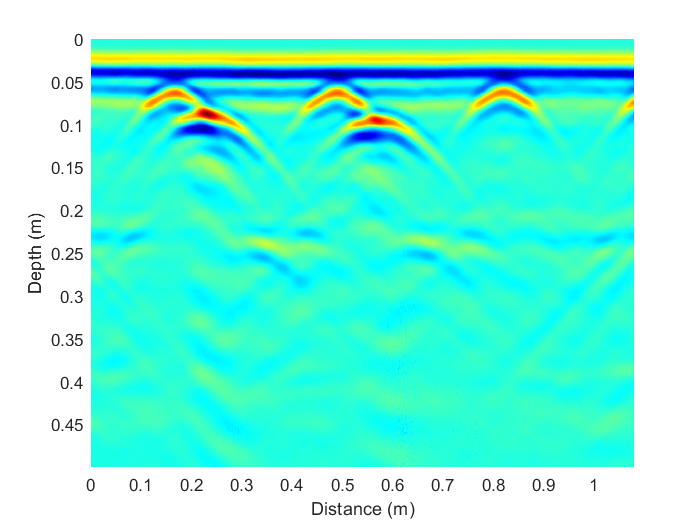

pdata2 = iadgain1(pdata1, 0.75);
plotbscan(pdata2, dataHeader, relPerm);

### Remove the direct wave reflection

Remove the direct wave reflection (or trend) to improve the B-Scan visualization, using **removetrend** function.

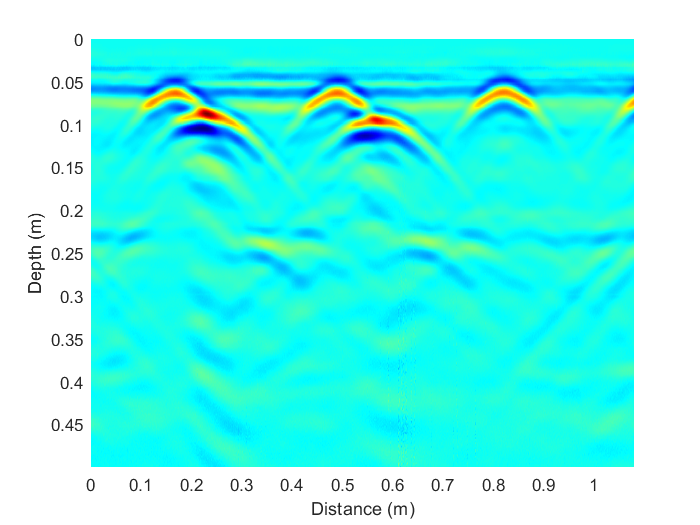

pdata3 = removetrend(pdata2,1);
plotbscan(pdata3, dataHeader, relPerm);

### Reduce the noise

Smooth or reduce the noise of the data to improve the B-Scan visualization, using **smoothscan** function.

pdata4 = smoothscan(pdata3, dataHeader);
plotbscan(pdata3, dataHeader, relPerm);